# **Response surface on E and F**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



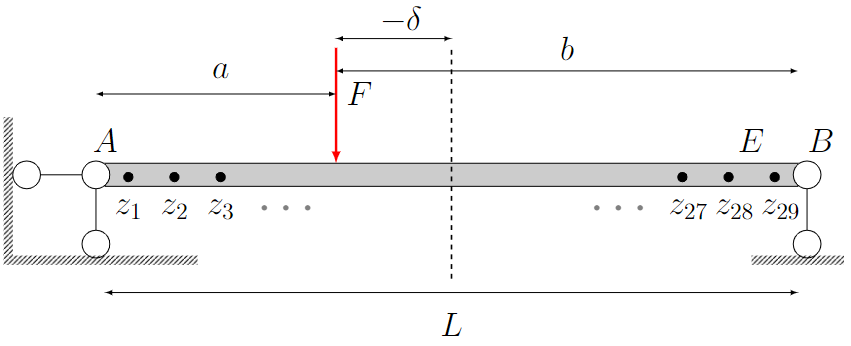

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        L = 30; % beam length (m)

**Computational model:**

$a = \frac{L}{2}- \delta$;$b = \frac{L}{2}+ \delta$


$$\mathcal{M}(\vec{\theta}) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(\vec{\theta})  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)z-z^3]}{6LEI} \ \ \ \ z> a
$$



$$\vec{\theta} = [E,\delta,F,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion, *F *is the loading force

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

## 3 - Plot response surface

Generate a synthetic ground truth without noise

E = 37e9;delta = -3.15; F = 28000N; noise =0

lower_limit_E = 10e9;
upper_limit_E = 50e9;
lower_limit_F = 20000;
upper_limit_F = 60000;

Measurement = GroundTruth(3.7e+10,-3.15,2.8e+04,1,0.0);
size(Measurement)

ans =      1    29


Coordinates and connections Ground truth

E = linspace(lower_limit_E, upper_limit_E, 1e2);
F = linspace(lower_limit_F, upper_limit_F, 1e2);  

[E_grid, F_grid]=meshgrid(E,F); 

E_grid_reshape = reshape(E_grid,[],1);
F_grid_reshape = reshape(F_grid,[],1);
X= [E_grid_reshape, F_grid_reshape];
FE_Realization_true = Deflection(X);

Calculate the error data for Ground truth surface square root


%%calculate the  Residual for the surrogate   

expNum = size(Measurement,1);% experiment number  N

Npoint = size(Measurement,2);% number of z [z1,z2,...,z28,z29]

Residual = []; % intitail value for Residual
ResidualSum = [];% intitail value for ResidualSum

%loop to calculate the ResidualSum 


error=(Measurement(1,:) - FE_Realization_true).^2;

Residual(:,1) = sum(error,2);


%Divide the number of experiment expNum  and monitored points number along
%the beam Npoint = 29
ResidualSum_true(:,1) = log(sum(Residual(:,1),2)/expNum/Npoint);

row = size(E_grid,1);
col = size(E_grid,2);
ResidualSum_true = reshape(ResidualSum_true,row,col);

plot the response surface for True

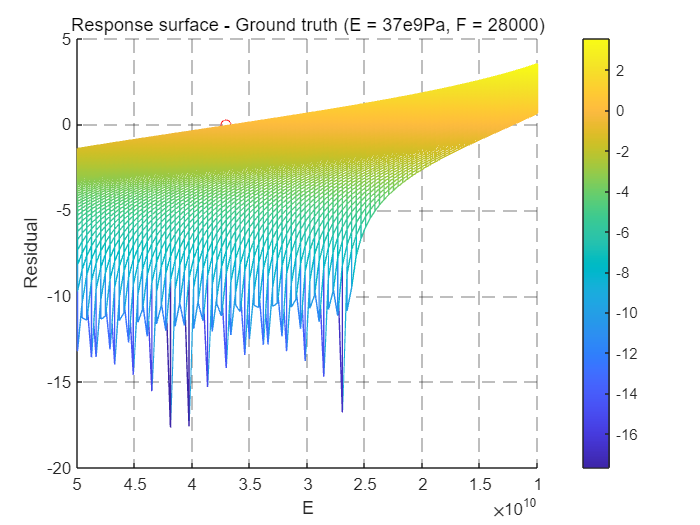

mesh(E_grid,F_grid,ResidualSum_true);
colorbar;
xlabel('E');ylabel('F');zlabel('Residual')
title('Response surface - Ground truth (E = 37e9Pa, F = 28000)');
set(gca,'ygrid','on','gridlinestyle','--','Gridalpha',0.4)
view(180,0)
hold on;
scatter(3.7e10,28000,'o','r');